# CMSE 821: Numerical Differential Equations / Final Exam

Student: Jorge A. Martinez Ortiz

Date Due: 12.14.2023

The solidification model is dictated by the following equations


$$\frac{\partial \phi}{\partial t} = -M\Big(\frac{\partial f}{\partial \phi} - \nabla \cdot \epsilon^2 \nabla \phi + m(T)\Big)$$


$\frac{\partial T}{\partial t} = \nabla^2 T + K \frac{\partial \phi}{\partial t}$,

with the following definitions


$$\frac{\partial f}{\partial \phi} = \frac{1}{2} \phi (1-\phi)(1-2\phi)$$



$$m(T) = \frac{\alpha}{\pi}\phi(1-\phi)\tan^{-1}[\gamma(T-T_m)].$$


We set the following values for the simulation parameters.


$$M = 3000$$



$$\alpha = 0.9$$



$$\gamma = 10$$



$$T_m = 1$$



$$K = 1.6$$


## Tasks

### Task 1. Discretization and initial conditions

For the discretization we let $Lx=Ly=9$. No-gradient Neumann boundary conditions are imposed on the four sides for both $\phi$ and $T$. Discretize the 2D domain with grid spacing $h=0.03$, such that we have $301 \times 301$grid points over the 2D domain. The initial condition of $\phi$ is a loose nucleus defined by


$$\phi_0 = \frac{1}{2}\Big[1-\tanh \Big(\frac{r-0.25}{0.015}\Big)\Big]\eta,$$


where $\eta$ is some uniformly distributed random noise between 0 and 1 at each point grid within the region of $\phi_0$.

The radius is defined by 

$r = \sqrt{(x-4.5)^2+(y-4.6)^2}$.

The initial temperature is uniformly zero throughout the domain. 

**Plot te initial conditions of **$\phi$** and **$T$

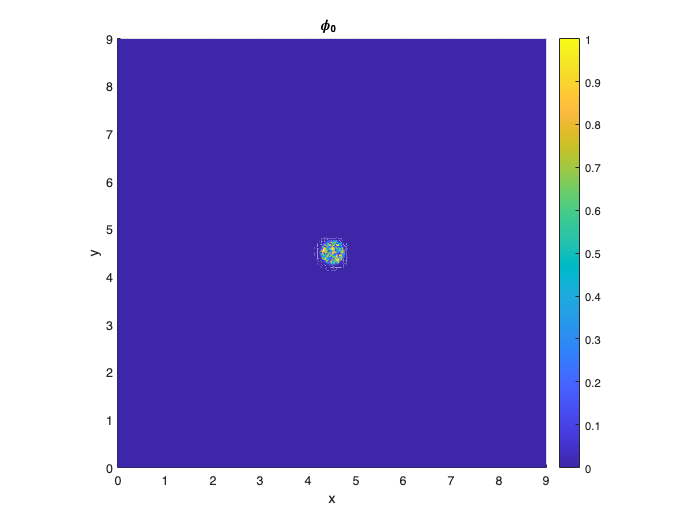

% Create a struct to define the parameters of the simulation
params = struct;
params.M        = 3000;
params.alpha    = 0.9;
params.epsilon  = 0.01;
params.gamma    = 10;
params.Tm       = 1;
params.K        = 1.6;
params.xlim     = [0 9];
params.ylim     = [0 9];
params.h        = 0.03;

% Instantiate class
cg = Crystal_growth(params,...                              % Parameters
                    @(x,y) phi_initial_condition(x,y),...   % Phi initial condition
                    @(x,y) T_initial_condition(x,y));       % T initial condition
figure
fdraw(cg.x,cg.y,cg.phi_naught,'title',"\phi_0 ")

### Task 2. Isotropic growth.

Use **Euler method **in time and **5-point** **stencil **for the Laplacians in the equations. The updates are specified as follows


$$\frac{\phi^{n+1}-\phi^n}{\Delta t} = -M\Big(\frac{\partial f}{\partial \phi} - \epsilon^2 \nabla^2 \phi + m(T)\Big)^n$$


$\frac{T^{n+1}-T^n}{\Delta t} = \nabla^2T^n+K \frac{\phi^{n+1}-\phi^n}{\Delta t}$.

Simulate the growth of the solid phase for a duration of 0.45 with $\Delta t = 0.0001.$ Grab snapshots of both $\phi$ and $T$ every 0.05 time period. 

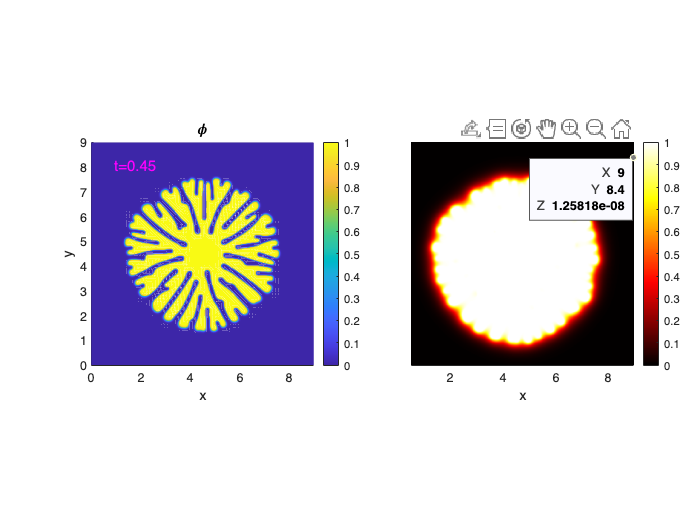

% Define run parameters
t_span  = [0 0.45];     % Time span
k       = 0.0001;       % Time step

figure
[phi,T] = animate(cg,t_span,k);

### Task 3. Surface Orientation.

The solid vector surface is given by


$$\nabla \phi = \Big(\frac{\partial \phi}{\partial x}, \frac{\partial \phi}{\partial y}\Big)$$


and it will be calculated with first order central differences. 

The inward-pointing unit vector of the solid surface is defined as 

$\vec{n} = \frac{\nabla \phi}{|\nabla \phi|}= (n_x,n_y)$.

Lastly, the surface orientation with respect to the coordinate system is defined as 

$\theta = \tan^{-1}\Big(\frac{n_y}{n_x}\Big)$.

Plot $|\nabla \phi|$, $\vec{n}$ and $\theta$.

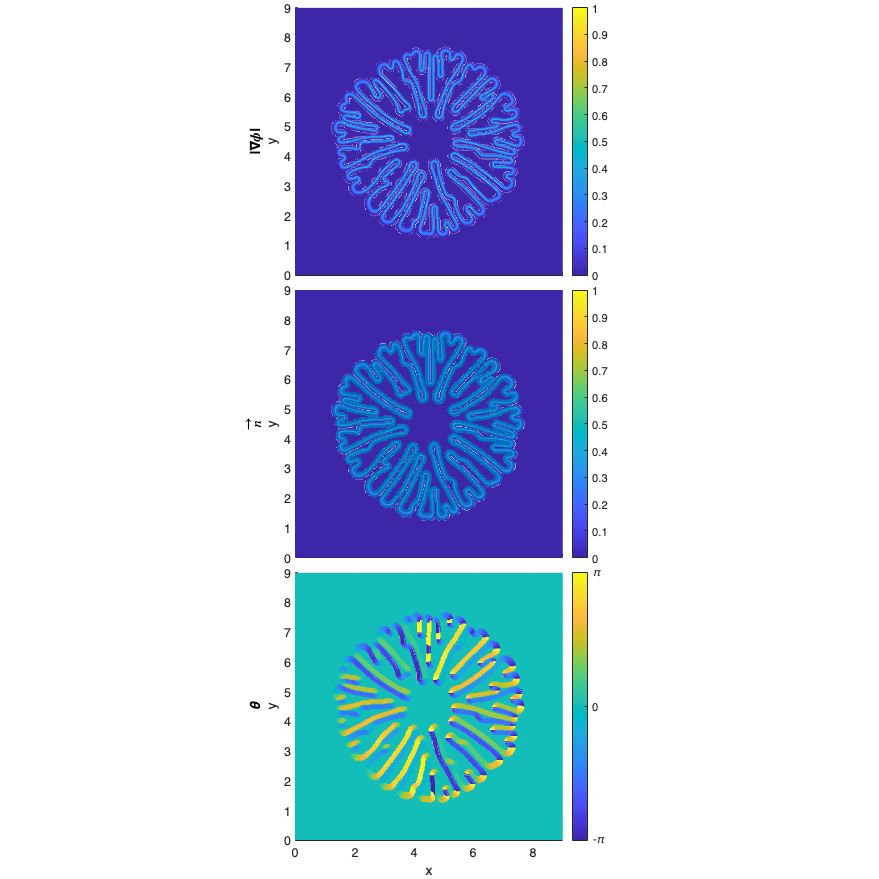

% Calculate gradient
[fx,fy,mag,idx] = grad(phi);

% Select points
mag(~idx) = 0;

% Calculate inward pointing vector and theta
[theta,nx,ny] = inward_vector(phi);

% Draw magnitude of the gradient
figure('Renderer', 'painters', 'Position', [0 0 1000 1000])
t = tiledlayout('vertical');
t.TileSpacing = 'tight';
t.Padding = 'tight';

nexttile
fdraw(cg.x,cg.y,mag);
xticklabels([])
xlabel("")
title("|\nabla\phi|",'Rotation',90,'Position',[-1 4.5 0]);


ax = nexttile;
fdraw(cg.x,cg.y,mag)
hold on
quiver(cg.x,cg.y,nx,ny)
xticklabels([])
xlabel("")
title("$$\vec{n}$$",'Rotation',90,'Position',[-1 4.5 0],'Interpreter','latex');

nexttile;
fdraw(cg.x,cg.y,theta,'bar_lim',[-pi pi],'bar_ticks',["-\pi","0","\pi"])
title("\theta",'Rotation',90,'Position',[-1 4.5 0]);

### Task 4. Anisotropic growth.

We have the following equations that will determine the anisotropic surface enrgy of the crystal


$$\epsilon(\theta) = \bar{\epsilon}[1 + \delta \cos(s \cdot (\theta - \theta_0))]$$


$\epsilon(\theta)' = - \bar{\epsilon} \delta s \sin(s \cdot (\theta - \theta_0))$.

We will set the following parameters


$$s = 6$$



$$\delta = 0.04$$



$$\bar{\epsilon} = 0.01$$



$$\theta_0 = 0.5$$


Using the same initial condition, time step size, and Euler method in tiem as in task 2, simulate the growth for a duration of 0.4. 

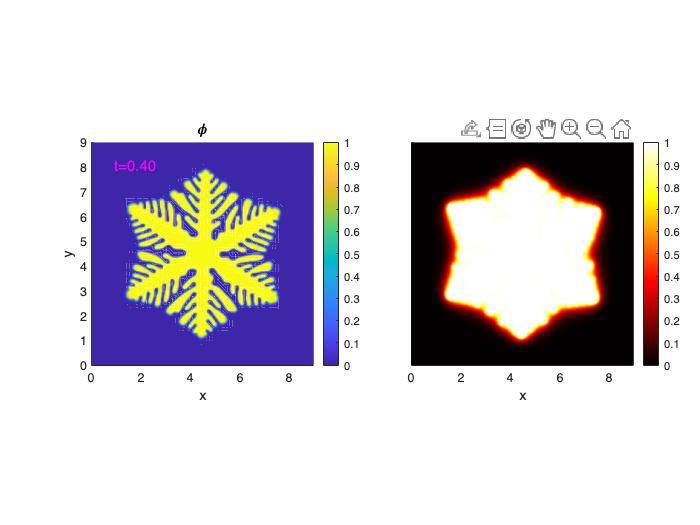

% Define scalar field parameters
epsilon         = 0.01;
delta           = 0.04;
s               = 6;
theta_naught    = 0.5;


% Update coefficient parameter(epsilon)
% The Crystal_growth class was implemented in such a way that it will
% detecth wether the coefficient of the laplacian is a consant or a
% function (scalar field). In the case that it is a function, it will
% correctly sample and average the values of the scalar field in order to
% obvtain the correct coefficient of the stencil;
params.epsilon  = @(phi)coefficient(phi,...
                                    epsilon,...
                                    delta,...
                                    s,...
                                    theta_naught);
% Instantiate class
cg = Crystal_growth(params,...
                    @(x,y) phi_initial_condition(x,y),...
                    @(x,y) T_initial_condition(x,y));


% Define run parameters
t_span  = [0 0.4];
k       = 0.0001;

figure
animate(cg,t_span,k);

### Task 5 Play with the code. 

We will change the initial temperature field to 


$$T_0 = \frac{x}{L_x} -0.3$$


The growth will be affected by the temperature gradient. Set $\theta_0 = 0.15$. Run the code of task 4 for a duration of 0.3. 

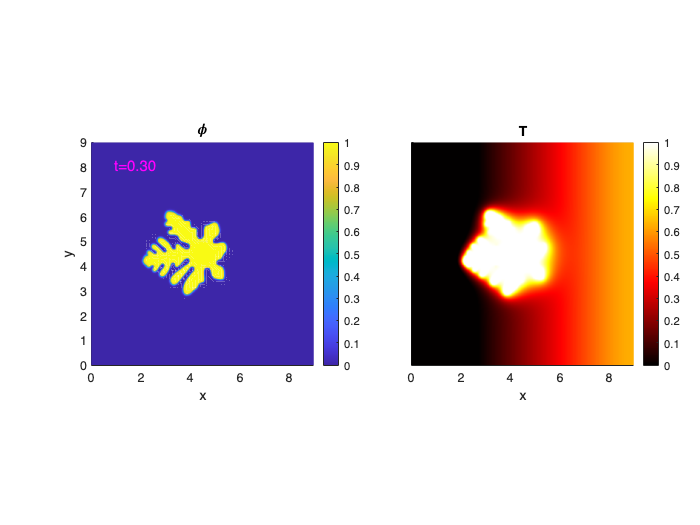

% Define scalar field parameters
epsilon         = 0.01;
delta           = 0.04;
s               = 6;
theta_naught    = 0.15;


% Define parameters
params.epsilon  = @ (phi)   coefficient(phi,...
                                        epsilon,...
                                        delta,...
                                        s,...
                                        theta_naught);

% Instantiate class, now with nonuniform boundary conditions in T
cg = Crystal_growth(params,...
                    @(x,y) phi_initial_condition(x,y),...
                    @(x,y) T_initial_condition_nonuniform(x,y));

% Define run parameters
t_span  = [0 0.3];
k       = 0.0001;

figure
profile on
[phi,T] = animate(cg,t_span,k);

### Task 6 Increase accuracy

Redo task 4 and task 5 with 9pt stencils and 6pt stencils respectively

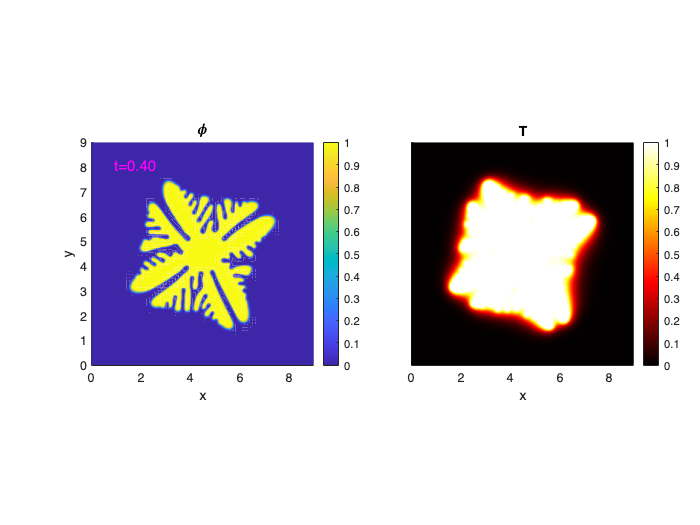

% Define scalar field parameters
epsilon         = 0.01;
delta           = 0.04;
s               = 4;        % Fourfold symmetry
theta_naught    = 0.5;

% Define parameters
params.epsilon  = @ (phi)   coefficient(phi,...
                                        epsilon,...
                                        delta,...
                                        s,...
                                        theta_naught);

% Define new stencils
five_pt         = [0  1  0;
                   1 -4  1;
                   0  1  0];

off_diag        = [1  0  1;
                   0 -4  0;
                   1  0  1];

six_pt_x        = [-1 0  1;
                   -2 0  2;
                   -1 0  1];

six_pt_y        = [-1 -2 -1;
                    0  0  0;
                    1  2  1];

% Construct the stencils. The crystal generation class will make sure to
% include the factors of (1/h^2)
mask.lap        = 2/3 * five_pt + 1/6 * off_diag;
mask.dx         = 1/8 * six_pt_x;
mask.dy         = 1/8 * six_pt_y;


% Instantiate class
cg = Crystal_growth(params,...
                    @(x,y) phi_initial_condition(x,y),...
                    @(x,y) T_initial_condition(x,y),...
                    mask);
% Define run parameters
t_span  = [0 0.4];
k       = 0.0001;

figure
animate(cg,t_span,k);

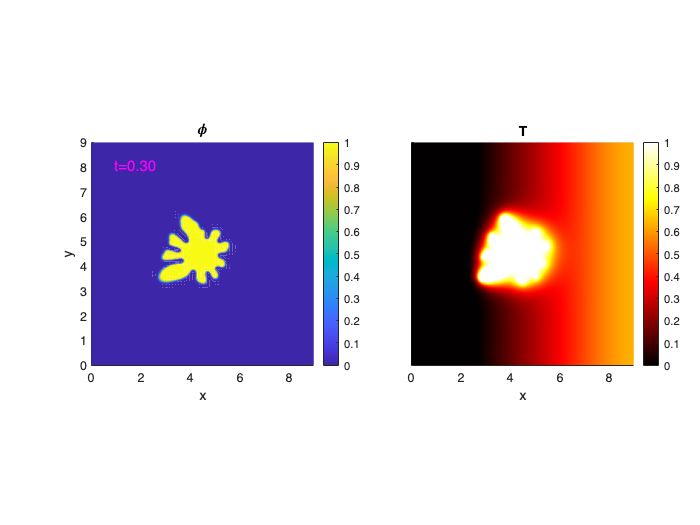

% Instantiate class
cg = Crystal_growth(params,...
                    @(x,y) phi_initial_condition(x,y),...
                    @(x,y) T_initial_condition_nonuniform(x,y),...
                    mask);

% Define run parameters
t_span  = [0 0.3];
k       = 0.0001;

figure
animate(cg,t_span,k);

## Functions

function phi_naught = phi_initial_condition(x,y)
    %INITIAL_CONDITION Generates the initial condition to the
    %problem given the discretizations along the x and y 
    % directions
    theta = (hypot(x-4.5,y-4.5)-0.25)/0.015;
    phi_naught = 1/2 * (1 - tanh(theta)) .* rand(size(theta));
end

function T_naught = T_initial_condition(x,y)
    T_naught = zeros(size(x));
end

function T_naught = T_initial_condition_nonuniform(x,y)
    T_naught    = x/x(end,end) - 0.3;
end

function [g,g_prime] = coefficient(phi,epsilon,delta,s,theta_naught)
    theta = inward_vector(phi);

    % Calculate the phase
    phase = s * (theta - theta_naught);

    % Calculate the coefficient scalar field
    g       =  epsilon * (1 + delta * cos(phase));
    g_prime = -epsilon * s * delta * sin(phase);
end

function [fx,fy,mag,idx] = grad(f)
    [fx,fy] = gradient(f);

    mag = hypot(fx,fy);
    idx = mag > 0.01;
end

function [theta,nx,ny] = inward_vector(f)
    % Allocate memory
    nx      = zeros(size(f));
    ny      = zeros(size(f));
    theta   = zeros(size(f));

    % Calculate gradient
    [fx,fy,mag,idx] = grad(f);

    % Calculate inward vector
    nx(idx) = fx(idx) ./ mag(idx);
    ny(idx) = fy(idx) ./ mag(idx);
    
    % Calculate angle
    theta(idx) = atan2(ny(idx),nx(idx));
end